**第8章 数值积分与数值微分**

### 8.6 数值微分

`若已知原型函数，可以通过第2章介绍的diff()函数求取各阶导数的解析解。但是如果函数表达式未知，只有实验数据，这时对相关的求导问题就不能用前面的方法获得问题的解析解了。要求解这样的问题，需要引入数值算法得出所需问题的数值解。这种对实验数据求导数通常称为数值微分。`

**8.6.1 问题的提出**

`对于给定的实验数据``(``或列表函数``)``的求导问题，最简单的方法就是利用差商来近似代替导数，比如利用向前差商近似代替导数`$f^{\prime } \left(x_0 \right)=\frac{f\left(x_0 +h\right)-f\left(x_0 \right)}{h}$，`类似地，也可以用向后差商近似代替导数`$f^{\prime } \left(x_0 \right)=\frac{f\left(x_0 \right)-f\left(x_0 -h\right)}{h}$，`或用中心差商近似代替导数`$f^{\prime } \left(x_0 \right)=\frac{f\left(x_0 +h\right)-f\left(x_0 -h\right)}{2h}$。`由上述几个公式可知，步长``h``越小，计算结果越准确。但从计算角度看，`$h$`越小，`$f\left(x_0 +h\right)$`，`$f\left(x_0 \right)$`与`$f\left(x_0 -h\right)$`越接近，直接相减会造成有效数字的严重损失，因此，需要合理选取步长，至于步长的合理选取可参阅相关参考书。`

**8.6.2 中心差分算法**

`数值求导有多种方法，这里只介绍一种具有`$o\left(\Delta t^4 \right)$`精度级的中心差分算法，该算法的一到四阶微分公式为`


$${y_i }^{\prime } =\frac{{-y}_{i+2} +8y_{i+1} -8y_{i-1} +y_{i-2} }{12\Delta t}$$



$${{y_i }^{\prime } }^{\prime } =\frac{{-y}_{i+2} +16y_{i+1} -30y_i +16y_{i-1} -y_{i-2} }{12\Delta t}$$



$${{{y_i }^{\prime } }^{\prime } }^{\prime } =\frac{{-y_{i+3} +8y}_{i+2} -13y_{i+1} +13y_{i-1} -8y_{i-2} +y_{i-3} }{8\Delta t^3 }$$



$$y_i^{\left(4\right)} =\frac{{-y_{i+3} +12y}_{i+2} -39y_{i+1} +56y_i -39y_{i-1} +12y_{i-2} -y_{i-3} }{6\Delta t^4 }$$


`由于该微分算法具有`$o\left(\Delta t^4 \right)$`级精度，因而即使`$\Delta t$`不趋于``0``时，仍能得出较好的近似微分、在给出算法的``MATLAB``实现之前，先介绍一下差分的``MATLAB``计算：`

`在MATLAB中，差分仍用函数diff()求得，` `其具体调用格式如下：`

`Y=diff(x,n)`

`Y=diff(A,n,dim)`

`其中x是给定的向量;A是给定的矩阵;n为求解差分的阶次，默认值为1;dim表示按维求解差分,dim=1(``默认状态``)` `时按计算差分;dim=2``时按行计算差分;返回值Y是得到的差分向量或矩阵，``Y``的长度``(``大小``)``比x(A)短(``小``)。`

`下面采用上述中心差分算法编写一个数值微分求解函数diff_ctr.m.程序的具体内容如下：`

`function [dy,dx]=diff_ctr(y,dt,n)`

`% 数值微分求解`

`% 输入参数：`

`%       ---y：给定的等间距的实测数据构成的向量`

`%       ---dt：自变量的间距`

`%       ---n：所需的求导阶次（1~4）`

`% 输出参数：`

`%       ---dy：得到的导数向量`

`%       ---dx：与dy相对应的向量`

`yx1=[y 0 0 0 0 0];yx2=[0 y 0 0 0 0];yx3=[0 0 y 0 0 0];`

`yx4=[0 0 0 y 0 0];yx5=[0 0 0 0 y 0];yx6=[0 0 0 0 0 y];`

`switch n`

`    case 1`

`        dy=(-diff(yx1)+7*diff(yx2)+7*diff(yx3)-diff(yx4))/(12*dt);`

`        L0=3;`

`    case 2`

`        dy=(-diff(yx1)+15*diff(yx2)-15*diff(yx3)+diff(yx4))/(12*dt^2);`

`        L0=3;`

`    case 3`

`        dy=(-diff(yx1)+7*diff(yx2)-6*diff(yx3)-6*diff(yx4)+...`

`            7*diff(yx5)-diff(yx6))/(8*dt^3);L0=5;`

`    case 4`

`        dy=(-diff(yx1)+11*diff(yx2)-28*diff(yx3)+28*diff(yx4)-...`

`            11*diff(yx5)+diff(yx6))/(6*dt^4);L0=5;`

`end`

`dy=dy(L0+1:end-L0);`

`dx=([1:length(dy)]+L0-2-(n>2))*dt;`

`该函数的调用格式为：[dy,dx] =diff_ctr(y,dt,n)`

`【例8-29``】利用数值微分求解方法求解函数`$y=e^{x^{0\ldotp 8} } \textrm{sin5x}$`的``1~4``阶导数，并与解析解比较。`

syms x;
y=exp(x^0.8)*sin(5*x)%求1~4阶导数的解析解
y1=diff(y,x); y2=diff(y,x,2); y3=diff(y,x,3); y4=diff(y,x,4);
h=0.05;x=0.05:h:10;
Y=eval(subs(y)); y11=subs(y1); y22=subs(y2); y33=subs(y3); y44=subs(y4);

y=[y11;y22;y33;y44];%求1~4阶导数的数值解，并和解析解比较
for k=1:4
    [dy,dx]=diff_ctr(Y,h,k);
    subplot(2,2,k)
    plot(x,y(k,:),dx,dy,':')
end

**8.6.3 梯度和法矢量的数值计算**

`n元函数`$F\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right)$`梯度的定义如下：`$\nabla F=\frac{\partial F}{\partial x_1 }e_1 +\frac{\partial F}{\partial x_2 }e_2 +\ldotp \ldotp \ldotp +\frac{\partial F}{\partial x_n }e_n$

`要求``n``元函数`$F\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right)$`的解析梯度值固然可以由函数``diff()或``jacobian()求解，然而求解解析梯度比较耗时，而且一般情况下数值解已能满足用户的需要，故需要了解一下MATLAB中数值梯度的求解。在MATLAB中，求解激值梯度函数是gradient()，该函数的调用格式为：`

`[Fx1,Fx``2,Fx``3,...,Fxn]=gradient(F,h)`

`[Fx1,Fx``2,Fx3,...,Fxn]=gradient(F,h``x1,hx2,...,hxn)`

`其中F是给定的``n``元函数`$F\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right)$`的函数值阵；``h``是指定各个方向上的点与点的间距，其默认值为``1；hx1，hx``2``，...，``hx``n``分别指定各个方向上的点与点的间距。`

`返回值Fx1，Fx``2``，Fx``3``，...，Fxn``是求得的数值梯度，它们并不是真正的梯度，实际的梯度值可以由`$F_{x_i } =\frac{F_{x_i } h_{x_i } }{d_{x_i } }\left(i=1,2,\ldotp \ldotp \ldotp ,n\right)$`求得。`$d_{x_i }$`为`$x_i$`生成网格的步距。`

`【例``8-30``】利用函数`$z=xe^{-x^2 -y^2 }$`生成区城`$\left\lbrack -2,2\right\rbrack \times \left\lbrack -2,2\right\rbrack$`的网格数据，使用数值方法由生成的数据解出梯度值，并研究得出结果的误差。`

%------求梯度的解析解-.-- -%
clf
syms x y;

$$y = \sin\left(5\,x\right)\,{\mathrm{e}}^{x^{4/5}}$$

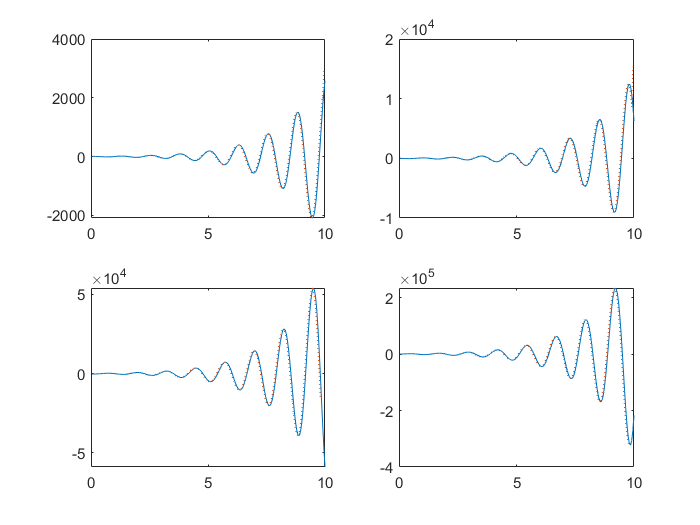

z=x*exp(-x^2-y^2);
zx=diff(z,x);
zy=diff(z,y);

% --绘图比较解析解和数值解---------%
[x,y]=meshgrid(-2:.2: 2);
z=x.*exp(-x.^2-y.^2);
[px,py]=gradient(z,.2,.2);
contour(x, y, z) , hold on , quiver(x, y, eval(zx), eval(zy)) , hold off
figure

contour(x, y, z) , hold on , quiver(x, y, px,py) , hold off
figure
surf(x,y,abs((px-eval(zx))./eval(zx))) %绘制dz/dx的误差曲面
figure
surf(x,y,abs((py-eval(zy))./eval(zy))) %绘制dz/dx的误差曲面

`对于二元函数，还可以给出法矢量的概念。法矢量作用在曲面上，而曲面对应于一个二元函数，所以法矢量是针对二元函数而言的，曲面的法线垂直于梯度的方向。MATLAB``提供的求解法矢量的函数是``surf``norm()，该函数的调用格式如下：`

`[Nx``，Ny``，Nz] =surf``norm(X``，Y``，Z)` `%``得到法矢量数值`

`surf``norm(X，Y，Z)` `%绘制矢量图`

`其中X，Y，Z表示三维表面的坐标数据，Nx，Ny，Nz是返回的方向数据。`

`【例``8-31``】以【例``8-30``】中的函数为例，先生成区域`$\left\lbrack -2,3\right\rbrack \times \left\lbrack -2,2\right\rbrack$`的一组数据，再绘制图形的法矢量。`

[X,Y]=meshgrid(-2:0.25:2,-1:0.2:1);
Z=X.*exp(-X.^2-Y.^2);
[U,V,W] =surfnorm(X,Y,Z); %计算法矢量
quiver3(X,Y,Z,U,V,W,0.5,'r'); %绘制箭头图形
hold on
surf(X,Y,Z)
%axis([-2 3 -2 2 -1 1]) %下面绘制的法矢量图和上面的图形效果是差不多的
figure
surfnorm(X,Y,Z) %绘制法矢量图

### 8.7 实验范例：自行车轮式物的运动轨迹

`1)``问题的提出`

`为了给平淡的自行车增添一份美感，同时也为了增加自行车的安全系数，一些骑车的人及一些自行车厂家在自行车的辐条上安装一款亮丽夺目的饰物。当有这种饰物的自行车在马路上驶过时，这种饰物就像游龙一样，对街边的行人闪过一道波浪形的轨迹，试画出它的图形。`

`2)``模型的假设`

`为了简化模型，假设如下：`

`●` `将路面视为一条通过原点的曲线`$f\left(x\right)$`，车轮视为一个半径为`$R$`的圆，圆心为`$O$`，该圆位于曲线`$f\left(x\right)$`的上方且与该曲线相切；`

`● 自行车在运行过程中，始终只与曲线`$f\left(x\right)$`的一个点接触；`

`●` `饰物``P``在离轮心距离为`$\bar{\textrm{OP}} =r$`处，显然`$r\le R$`；`

`●` `车轮与路面作无滑动的滚动。`

`3)``模型的建立`

`设`$\textrm{OP}$`与圆交于`$A$`点，现以`$A$`点为初始接触点，圆``(``即车轮``)``滚过`$\theta$`角后，圆与曲线的接触点变为`$B$`，圆心从`$O$`移到`$O^{\prime }$`，饰物`$P$`从原先位置移到`$P^{\prime }$`，如图所示。`

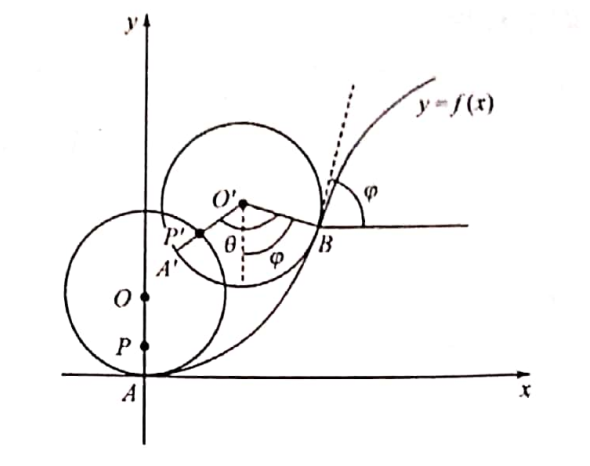

`设三点坐标为`$B\left(x_0 ,y_0 \right),O^{\prime } \left(X,Y\right),P^{\prime } \left(x,y\right),$`则`$\widehat{BA'}$$=R\theta =$$\widehat{BA}$$=\int_0^{x_0 } \sqrt{1+{\left\lbrack f^{\prime } \left(x\right)\right\rbrack }^2 }\textrm{dx}$

因此$\theta =\frac{1}{R}\int_0^{x_0 } \sqrt{1+{\left\lbrack f^{\prime } \left(x\right)\right\rbrack }^2 }\textrm{dx}$

`易知`$O^{\prime } \left(X,Y\right)$`在曲线`$y=f\left(x\right)$`过`$B$`点的法线的上侧且`$\bar{O^{\prime } B} =R$`，即`


$$\left\lbrace \begin{array}{cc}
Y-f\left(x_0 \right)=-\frac{1}{f^{\prime } \left(x_0 \right)}\left(X-x_0 \right) & \\
{\left(X-x_0 \right)}^2 +{\left(Y-f\left(x_0 \right)\right)}^2 =R^2  & 
\end{array}\right.$$


解得$\left\lbrace \begin{array}{cc}
X=x_0 -\frac{{\textrm{Rf}}^{\prime } \left(x_0 \right)}{\sqrt{1+{\left\lbrack f^{\prime } \left(x_0 \right)\right\rbrack }^2 }} & \\
Y=f\left(x_0 \right)+\frac{R}{\sqrt{1+{\left\lbrack f^{\prime } \left(x_0 \right)\right\rbrack }^2 }} & 
\end{array}\right.$

又对P'(x,y)有$\left\lbrace \begin{array}{cc}
x=X-\textrm{rsin}\left(\theta -\varphi \right) & \\
y=Y-\textrm{rcos}\left(\theta -\varphi \right) & 
\end{array}\right.$

其中$\left\lbrace \begin{array}{cc}
\varphi =\arctan \left(f^{\prime } \left(x_0 \right)\right) & \\
\theta =\frac{1}{R}\int_0^{x_0 } \sqrt{1+{\left\lbrack f^{\prime } \left(x\right)\right\rbrack }^2 }\textrm{dx} & 
\end{array}\right.$

所以饰物的运动轨迹为$\left\lbrace \begin{array}{cc}
x=x_0 -\frac{{\textrm{Rf}}^{\prime } \left(x_0 \right)}{\sqrt{1+{\left\lbrack f^{\prime } \left(x_0 \right)\right\rbrack }^2 }}-\textrm{rsin}\left(\theta -\varphi \right) & \\
Y=f\left(x_0 \right)+\frac{R}{\sqrt{1+{\left\lbrack f^{\prime } \left(x_0 \right)\right\rbrack }^2 }}-\textrm{rcos}\left(\theta -\varphi \right) & 
\end{array}\right.$

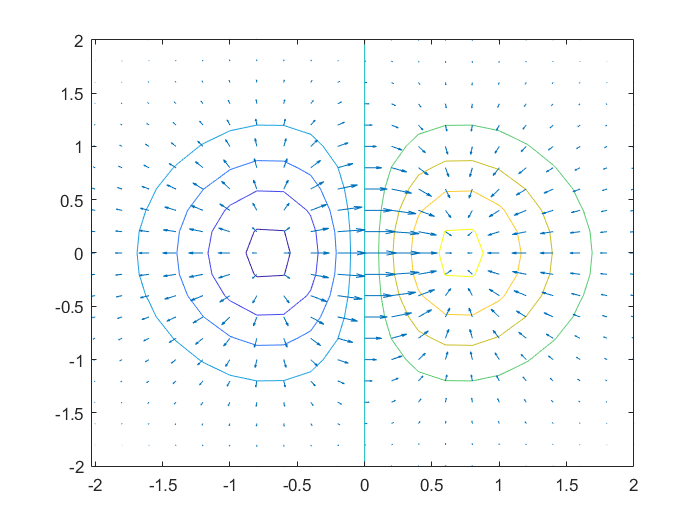

R=1;r=0.7*R;
f=@(x)-2*cos(0.2*x) +2; %定义函数f(x)

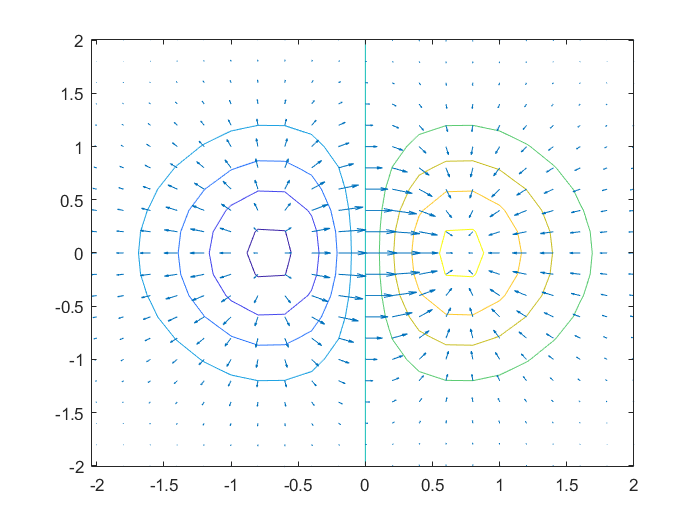

df=@(x)0.4*sin(0.2*x); %定义函数df(x)/dx
x0=eps:0.1:25;

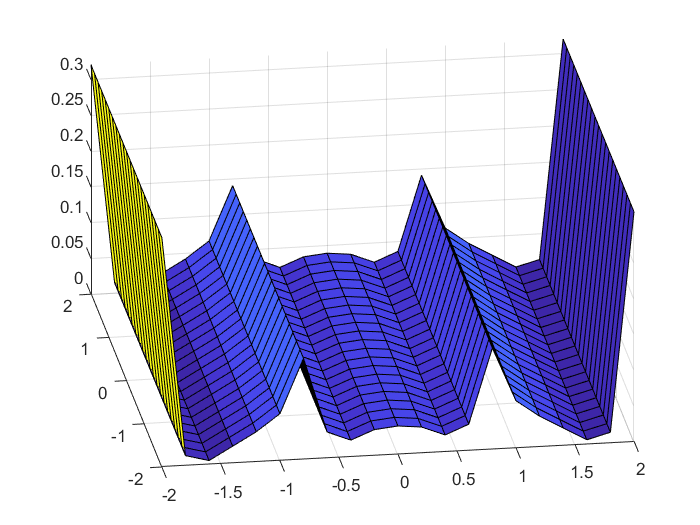

set(gcf,'DoubleBuffer','on'); %设置图形窗口的渲染效果
h=ezplot('-2*cos(0.2*x)+2',[-4,30]);

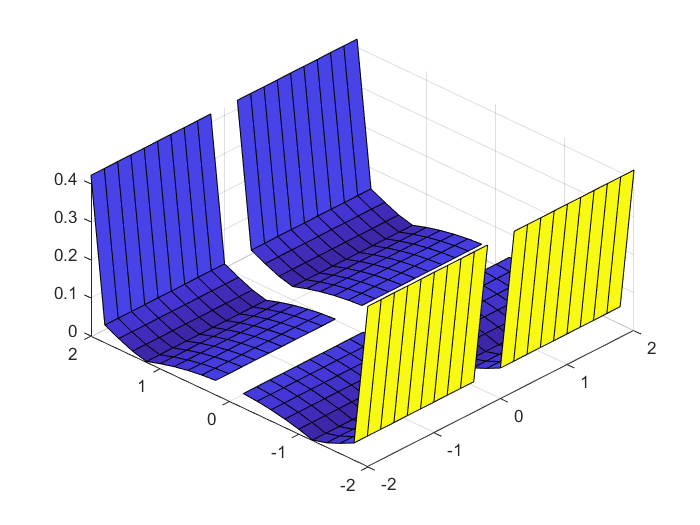

axis equal
ylim([-10,15])

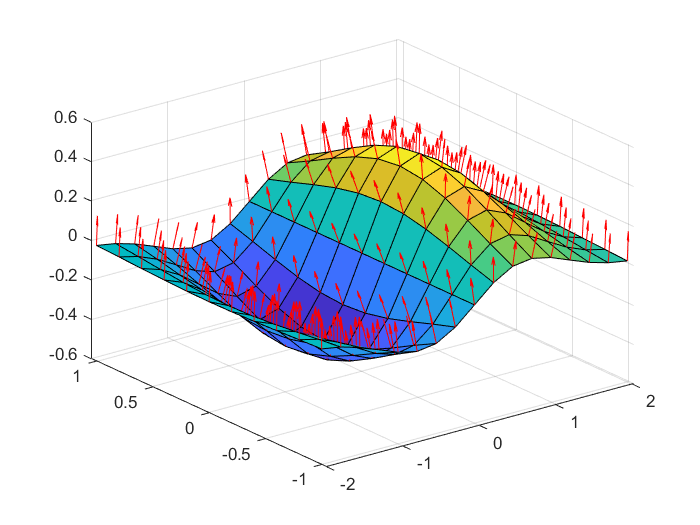

hold on
t=linspace(0,2*pi,length(x0));
h1=plot(R*(exp(i*t) +i));
phi=atan(df(x0(1))); %计算phi
theta=1/R*quadl(@(x)sqrt(1+df(x).^2),0,x0(1)); %计算theta
x=x0(1)-R*df(x0(1))/sqrt(1+df(x0(1))^2)-r*sin(theta-phi);
y=f(x0(1))+R/sqrt(1+df(x0(1))^2) -r*cos(theta-phi);
X=x0(1)-R*df(x0(1))/sqrt(1+df(x0(1))^2);
Y=(x0(1))+R/sqrt(1+df(x0(1))^2);
h2=plot(X,Y,'g.');
h3=plot(x,y,'r*');
h4=plot(x,y,'r','LineWidth',2);

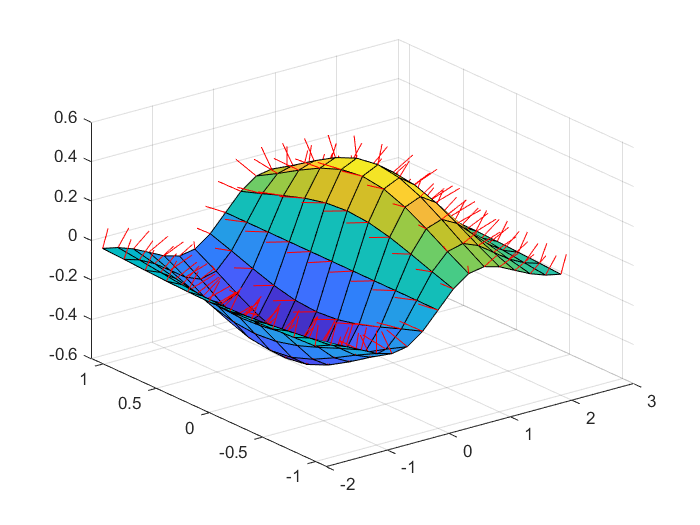

Z1=[x];Z2=[y];
for k=2:length(x0) %制作动画
    phi1=atan(df(x0(k))); theta1=1/R*quadl(@(x)sqrt(1+df(x).^2),0,x0(k));

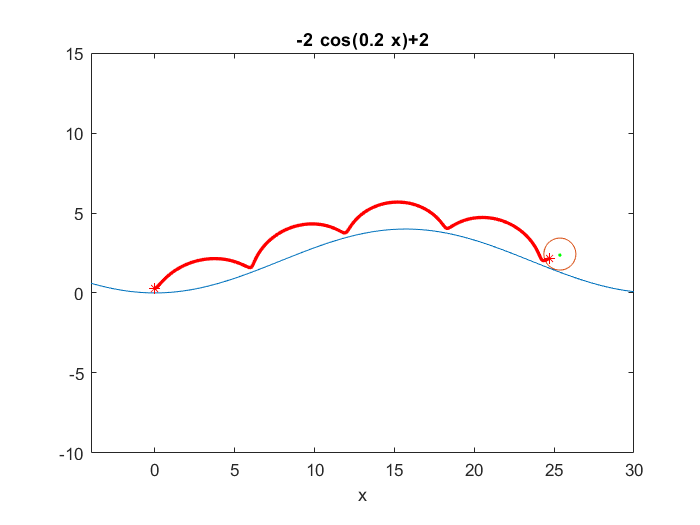

    C1=x0(k)-R*df(x0(k))/sqrt(1+df(x0(k))^2)-r*sin(theta1-phi1);
    C2=f(x0(k))+R/sqrt(1+df(x0(k))^2)-r*cos(theta1-phi1);
    X=x0(k)-R*df(x0(k))/sqrt(1+df(x0(k))^2);
    Y=f(x0(k))+R/sqrt(1+df(x0(k))^2);
    %更新车轮的坐标
    set(h1,'Xdata',real(R*(exp(i*t)+i))+x0(k)-R*sin(phi1),'Ydata',imag(R*(exp(i*t)+i))+f(x0(k)))
    set(h2,'Xdata',X,'Ydata',Y) %更新O'点的坐标
    Z1=[Z1,C1];Z2=[Z2,C2];
    set(h3,'Xdata',[x,C1],'Ydata',[y,C2]) %更新P点的坐标
    set(h4,'Xdata',Z1,'Ydata',Z2)
    pause(0.1) %暂停0.1s
end

`说明：上述例题是以函数`$f\left(x\right)=-2\textrm{cos0}\ldotp 2x+2$`为例制作动画的。`       